clear all;
close all;
clc;

# Final plot

Load the data

HK_CR_R_all_G = load("HK_CR_R_all.mat");
HK_CR_R_all_G = HK_CR_R_all_G.HK_CR_R_all;
HK_CR_R_recall_values_all_G = load("HK_CR_R_recall_values_all.mat");
HK_CR_R_recall_values_all_G = HK_CR_R_recall_values_all_G.HK_CR_R_recall_values_all;
HK_CG_G_all_G = load("HK_CG_G_all.mat");
HK_CG_G_all_G = HK_CG_G_all_G.HK_CG_G_all;
HK_CG_G_recall_values_all_G = load("HK_CG_G_recall_values_all.mat");
HK_CG_G_recall_values_all_G = HK_CG_G_recall_values_all_G.HK_CG_G_recall_values_all;

HK_CG_G_recall_values_all_G =          0         0         0         0   99.2793         0         0         0         0   99.2793         0         0         0         0   98.9189         0         0         0         0   98.9189         0         0         0         0   98.7387         0         0         0         0   98.1982         0         0         0         0   97.1171         0         0         0         0   94.7748         0         0         0         0   90.9910         0         0         0         0   85.7658
         0         0         0         0   99.2793         0         0         0         0   98.9189         0         0         0         0   98.9189         0         0         0         0   98.9189         0         0         0         0   98.7387         0         0         0         0   98.0180         0         0         0         0   97.2973         0         0         0         0   94.5946         0         0         0         0   90.8108         0         


% Results of LocalT2
results_LocalT2 = load("results_LocalT2.mat");
results_LocalT2 = results_LocalT2.results;

% Results of LocalGini
results_LocalGini = load("results_LocalGini.mat");
results_LocalGini = results_LocalGini.results;

## Extract the data i want for the plot

% Extract data for localT2
fieldNames = fieldnames(results_LocalT2);

% Loop through each field and create a variable with the same name
for i = 1:length(fieldNames)
    % Get the current field name
    fieldName = fieldNames{i};
    
    % Create a variable in the base workspace with the same name as the field
    % and assign to this variable the content of the corresponding field
    assignin('base', fieldName, results_LocalT2.(fieldName));
end

% Change names
mean_HK_CR_R_all_LT2 = mean_HK_CG_G_all;
mean_HK_CG_G_recall_values_all_LT2 = mean_HK_CG_G_recall_values_all;
mean_HK_CR_R_all_LT2 = mean_HK_CR_R_all;
mean_HK_CR_R_recall_values_all_LT2 = mean_HK_CR_R_recall_values_all;
std_HK_CG_G_all_LT2 = std_HK_CG_G_all;
std_HK_CG_G_recall_values_all_LT2 = std_HK_CG_G_recall_values_all;
std_HK_CR_R_all_LT2 = std_HK_CR_R_all;
std_HK_CR_R_recall_values_all_LT2 = std_HK_CR_R_recall_values_all;

% Extract data for localGini
fieldNames = fieldnames(results_LocalGini);

% Loop through each field and create a variable with the same name
for i = 1:length(fieldNames)
    % Get the current field name
    fieldName = fieldNames{i};
    
    % Create a variable in the base workspace with the same name as the field
    % and assign to this variable the content of the corresponding field
    assignin('base', fieldName, results_LocalGini.(fieldName));
end

% Change names
mean_HK_CR_R_all_LG = mean_HK_CG_G_all;
mean_HK_CG_G_recall_values_all_LG = mean_HK_CG_G_recall_values_all;
mean_HK_CR_R_all_LG = mean_HK_CR_R_all;
mean_HK_CR_R_recall_values_all_LG = mean_HK_CR_R_recall_values_all;
std_HK_CG_G_all_LG = std_HK_CG_G_all;
std_HK_CG_G_recall_values_all_LG = std_HK_CG_G_recall_values_all;
std_HK_CR_R_all_LG = std_HK_CR_R_all;
std_HK_CR_R_recall_values_all_LG = std_HK_CR_R_recall_values_all;

## Try to create the HKR plot

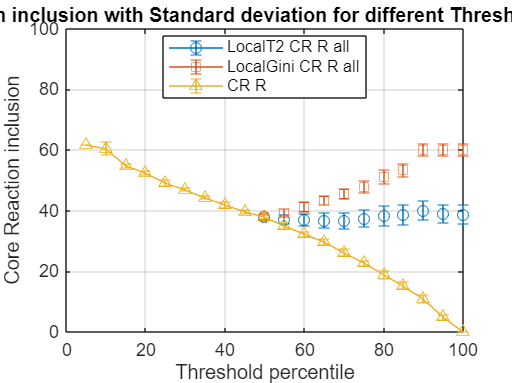

% Definir los valores de upper_p de 0 a 100
upper_p_values = 1:1:100;
upper_p_values_LT2_LG = 100:-5:50;

% Calcular medias y desviaciones estándar
mean_HK_CR_R = mean(HK_CR_R_all_G, 1, 'omitnan');
std_HK_CR_R = std(HK_CR_R_all_G, 0, 1, 'omitnan');
mean_HK_CG_G = mean(HK_CG_G_all_G, 1, 'omitnan');
std_HK_CG_G = std(HK_CG_G_all_G, 0, 1, 'omitnan');

% Extraer datos para localT2 y localGini y renombrar las variables
fieldNames_LocalT2 = fieldnames(results_LocalT2);
for i = 1:length(fieldNames_LocalT2)
    fieldName = fieldNames_LocalT2{i};
    assignin('base', fieldName, results_LocalT2.(fieldName));
end

mean_HK_CR_R_all_LT2 = mean_HK_CR_R_all;
std_HK_CR_R_all_LT2 = std_HK_CR_R_all;

fieldNames_LocalGini = fieldnames(results_LocalGini);
for i = 1:length(fieldNames_LocalGini)
    fieldName = fieldNames_LocalGini{i};
    assignin('base', fieldName, results_LocalGini.(fieldName));
end

mean_HK_CR_R_all_LG = mean_HK_CR_R_all;
std_HK_CR_R_all_LG = std_HK_CR_R_all;

% Crear vectores completos de NaN para los datos expandidos
mean_HK_CR_R_all_LT2_expanded = nan(1, length(upper_p_values));
std_HK_CR_R_all_LT2_expanded = nan(1, length(upper_p_values));
mean_HK_CR_R_all_LG_expanded = nan(1, length(upper_p_values));
std_HK_CR_R_all_LG_expanded = nan(1, length(upper_p_values));

% Asignar los datos a los lugares correctos en el rango de 50 a 100
mean_HK_CR_R_all_LT2_expanded(upper_p_values_LT2_LG) = mean_HK_CR_R_all_LT2;
std_HK_CR_R_all_LT2_expanded(upper_p_values_LT2_LG) = std_HK_CR_R_all_LT2;
mean_HK_CR_R_all_LG_expanded(upper_p_values_LT2_LG) = mean_HK_CR_R_all_LG;
std_HK_CR_R_all_LG_expanded(upper_p_values_LT2_LG) = std_HK_CR_R_all_LG;

% Identificar índices válidos (no ceros) para las series amarilla, roja y azul
validIndices_Yellow = mean_HK_CG_G ~= 0;
validIndices_Red = mean_HK_CR_R_all_LG_expanded ~= 0;
validIndices_Blue = mean_HK_CR_R_all_LT2_expanded ~= 0;

% Aquí se definen las variables de recall como placeholders, ya que no fueron proporcionadas

mean_HK_CR_R_recall_values_all_LT2_expanded = nan(1, length(upper_p_values));  % Reemplazar con los datos reales
std_HK_CR_R_recall_values_all_LT2_expanded = nan(1, length(upper_p_values));   % Reemplazar con los datos reales
mean_HK_CR_R_recall_values_all_LG = nan(1, length(upper_p_values));            % Reemplazar con los datos reales
std_HK_CR_R_recall_values_all_LG = nan(1, length(upper_p_values)); 

% Reemplazar con los datos reales
mean_HK_CR_R_recall_values_all_LT2_expanded(upper_p_values_LT2_LG) = mean_HK_CG_G_recall_values_all_LT2;
std_HK_CR_R_recall_values_all_LT2_expanded(upper_p_values_LT2_LG) = std_HK_CG_G_recall_values_all_LT2;
mean_HK_CR_R_recall_values_all_LG(upper_p_values_LT2_LG) = mean_HK_CG_G_recall_values_all_LG;
std_HK_CR_R_recall_values_all_LG(upper_p_values_LT2_LG) = std_HK_CG_G_recall_values_all_LG;


% Plotear los resultados
figure;

% Plot para HK_CR_R_all y HK_CG_G vs. upper_p con datos LocalT2 y LocalGini
subplot(1,1,1);
errorbar(upper_p_values(validIndices_Blue), mean_HK_CR_R_all_LT2_expanded(validIndices_Blue), std_HK_CR_R_all_LT2_expanded(validIndices_Blue), '-o', 'DisplayName', 'LocalT2 CR R all');
hold on;
errorbar(upper_p_values(validIndices_Red), mean_HK_CR_R_all_LG_expanded(validIndices_Red), std_HK_CR_R_all_LG_expanded(validIndices_Red), '-s', 'DisplayName', 'LocalGini CR R all');
errorbar(upper_p_values(validIndices_Yellow), mean_HK_CR_R(validIndices_Yellow), std_HK_CR_R(validIndices_Yellow), '-^', 'DisplayName', 'CR R');
hold off;
xlabel("Threshold percentile");
ylabel('Core Reaction inclusion');
title('Core reaction inclusion with Standard deviation for different Thresholding method');
legend('Location', 'best');
grid on;
ylim([0 100])
xlim([0 100]); % Limitar el eje x de 0 a 100
hold off;
saveas(gcf, 'figure_core_react.png');

## Plot para HK_CR_R_all recall values y HK_CG_G vs. upper_p con datos LocalT2 y LocalGini 

TRY TO PLOT THE NORMALIZED RECALL

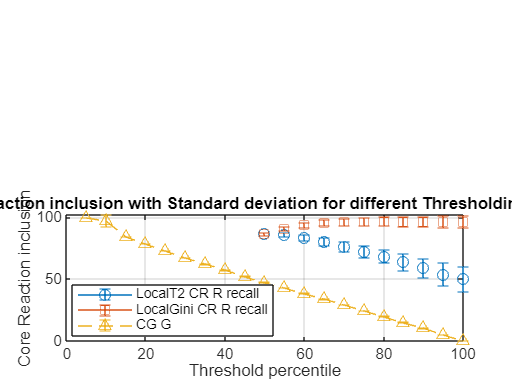

figure;

subplot(2,1,2);
errorbar(upper_p_values(validIndices_Blue), mean_HK_CR_R_recall_values_all_LT2_expanded(validIndices_Blue), std_HK_CR_R_recall_values_all_LT2_expanded(validIndices_Blue), 'o-', 'DisplayName', 'LocalT2 CR R recall');
hold on;
errorbar(upper_p_values(validIndices_Red), mean_HK_CR_R_recall_values_all_LG(validIndices_Red), std_HK_CR_R_recall_values_all_LG(validIndices_Red), 's-', 'DisplayName', 'LocalGini CR R recall');
errorbar(upper_p_values(validIndices_Yellow), mean_HK_CG_G(validIndices_Yellow), std_HK_CG_G(validIndices_Yellow), '^--', 'DisplayName', 'CG G');
hold off;
xlabel("Threshold percentile");
ylabel('Core Reaction inclusion');
title('Core reaction inclusion with Standard deviation for different Thresholding method');
legend('Location', 'best');
grid on;
xlim([0 100]); % Limitar el eje x de 0 a 100
hold off;
saveas(gcf, 'figure_norm_recall.png')